clc
clear
load('REFERENCE.MAT'); %Abriendo la base de datos

[F1,C] = size(REFERENCE)

F1 = 8528

C = 2

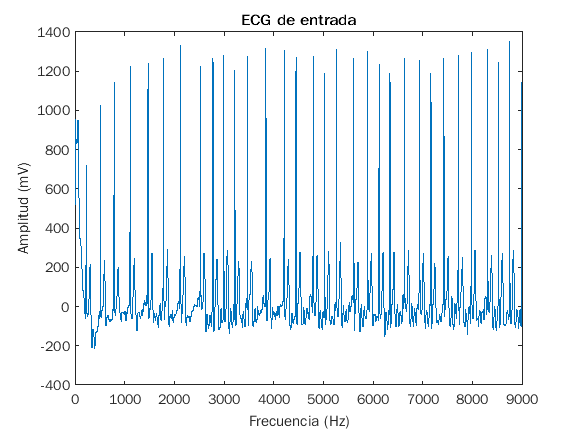

fs = 300;
%Ganancia de prueba
g = 1500;

s= load(REFERENCE(4,1)); %señal a tratar

plot(s.val)
xlabel('Frecuencia (Hz)')
ylabel('Amplitud (mV)')
title('ECG de entrada')

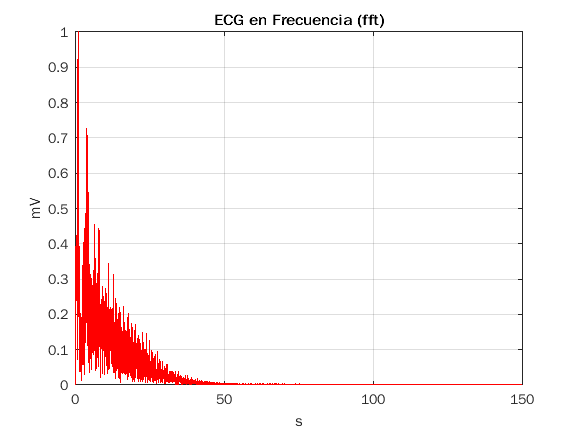


s.val = s.val/g;
s.val = (s.val - mean(s.val))/std(s.val);
t = (1:1:length(s.val))*(1/fs);

%% FFT
F = fft(s.val);
F = abs(F);
F = F(1:ceil(end/2));
F = F/max(F);

L = length(F);
f = (1:1:L)*((fs/2)/L);
figure
%Grafica fft
plot(f,F, 'r')
ylabel('mV')
xlabel('s')
title('ECG en Frecuencia (fft)');
grid on
xlim([0 150])

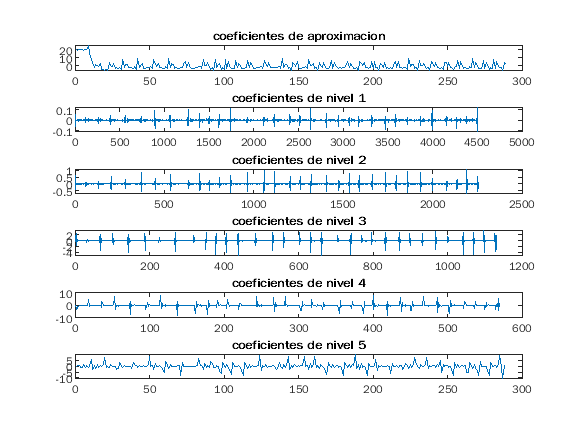


%wavelet 5 niveles
[cw,lw]=wavedec(s.val,5,'db5');
%coeficientes de aproximacion
approx=appcoef(cw,lw,'db5');
%coeficientes de detalle
[cd1,cd2,cd3,cd4,cd5]=detcoef(cw,lw,[1,2,3,4,5]);

subplot (6,1,1)
plot(approx)
title('coeficientes de aproximacion');
subplot (6,1,2)
plot(cd1)
title('coeficientes de nivel 1');
subplot (6,1,3)
plot(cd2)
title('coeficientes de nivel 2');
subplot (6,1,4)
plot(cd3)
title('coeficientes de nivel 3');
subplot (6,1,5)
plot(cd4)
title('coeficientes de nivel 4');
subplot (6,1,6)
plot(cd5)
title('coeficientes de nivel 5');

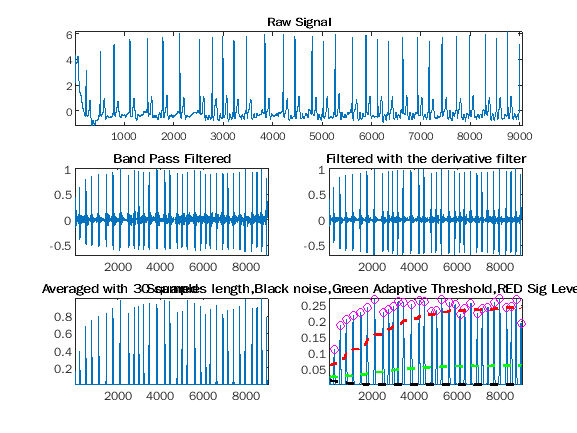

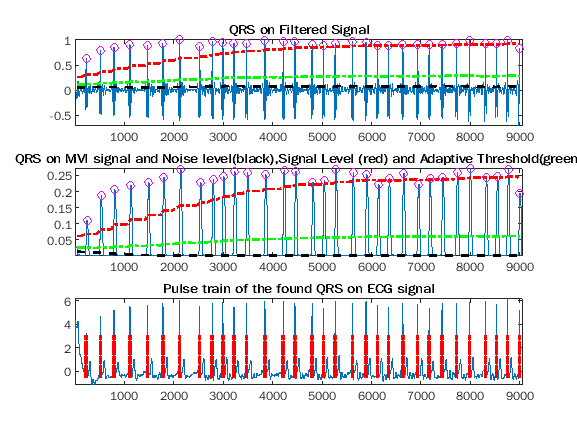

qrs_amp =     0.6313    0.7914    0.8524    0.9003    0.8931    0.9326    1.0000    0.8798    0.9642    0.9575    0.9332    0.9357    0.9906    0.9779    0.9727    0.9153    0.8917    0.9334    0.9679    0.9509    0.8919    0.8942    0.9179    0.9053    0.9159    0.9127    0.9395    0.9835    0.9251    0.9292    0.9917    0.8215


qrs_pos =          227         513         790        1113        1471        1780        2122        2524        2778        2993        3217        3472        3843        4214        4450        4798        5025        5264        5612        5889        6124        6341        6634        6935        7166        7427        7718        7981        8305        8529        8751        8992


delay = 22.5000



[qrs_amp,qrs_pos,delay]=pan_tompkin(s.val,300,1)


figure
n=length(qrs_pos)

n = 32

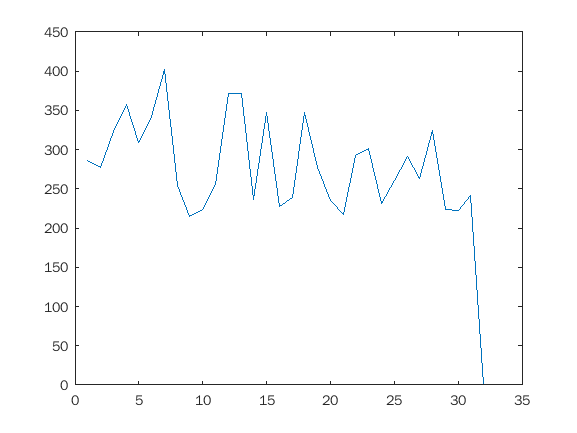

xs=zeros(1,n);
for i=2:1:n
   xs(i-1)=qrs_pos(i)-qrs_pos(i-1);
end
plot(xs)